# Temperatura - K-Means Clustering

I sensori contrassegnati da una croce rossa sono stati eliminati perché non affidabili:

5, 15, 18, 26, 28, 47, 48, 49, 50, 51, 52, 53 e 54 (con la vecchia notazione).

Purtroppo, eliminando delle righe, i sensori vengono "rinominati":

sensori dal 6 al 14: num_riga - 1

sensori dal 16 al 17: num_riga - 2

sensori dal 19 al 25: num_riga - 3

sensore 27: num_riga - 4

sensori dal 29 in poi: num_riga - 5

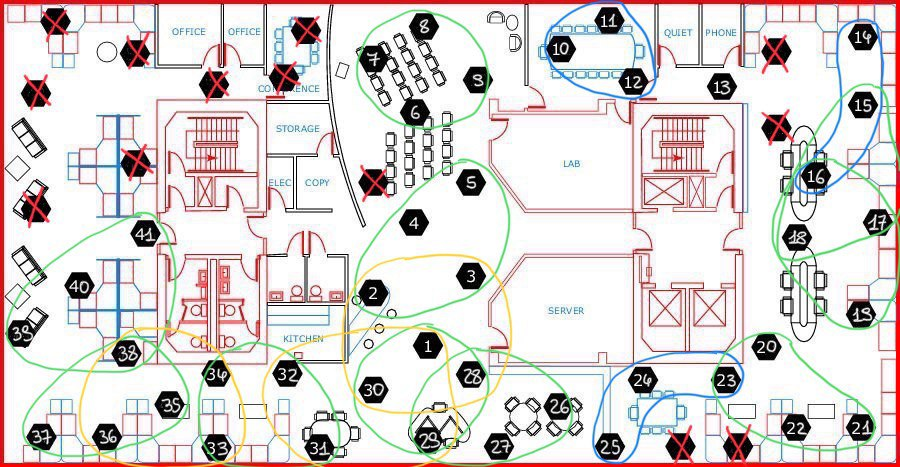

% Carica tutti i dati
load Data.mat

% Numero sensori
num_sensori = 46;

% Variabile: temperatura
j=1;

% Prende tutti i sensori da 1 a 46
for i=1:num_sensori
  
    % Trova le righe di Data che abbiano i come valore della seconda colonna
    S{i}=find(Data(:,2)==i); % cell array, contiene gli indici delle righe 
    x{i,j}=Data(S{i},j+2); % i-esimo sensore, prima variabile (temperatura)

    % Filtraggio e interpolazione dati
    
    % Identifica gli outliers
    detect_x{i,j} = isoutlier(x{i,j});

    % Rimuove gli outliers
    x{i,j}= rmoutliers(x{i,j});  
    
    % Prende le epoch temporali dalla prima riga di Data (dell'i-esimo sensore)
    t{i,j}=Data(S{i},1);
   
    % Toglie quelle che corrispondono agli outliers
    t{i,j}=t{i,j}(~detect_x{i,j});
    
    % Toglie i doppioni
    [tu{i,j},IA,IC] = unique(t{i,j});
   
    % Prende i corrispettivi valori della variabile in base alle epoch
    xu{i,j}=x{i,j}(IA);

    % Interpola i valori della variabile con la risoluzione voluta
    xint{i,j} = interp1(tu{i,j}, xu{i,j}, [1:10:6e4]);
end

% Elenco dei sensori da escludere
sensori_da_escludere = [5 15 18 26 28];

% controllo: size(xint{1, 1})

% Numero di punti temporali
num_punti_temporali = length(xint{1, 1});  % Lunghezza del primo vettore colonna (variabile temperatura)
                                           % del primo sensore (è uguale per tutti)
                                           
% Prealloca la matrice (nulla) per contenere le misure della prima colonna di ciascun sensore

% Riduciamo il numero di righe in base ai sensori da escludere
num_sensori_inclusi = num_sensori - length(sensori_da_escludere);
matrice_misure = zeros(num_sensori_inclusi, num_punti_temporali);

% Indice per le righe della matrice
indice_riga = 1;

% Ciclo su ciascun sensore per estrarre i dati della prima colonna
for k = 1:num_sensori
    % Controlla se il sensore è nella lista da escludere
    if ismember(k, sensori_da_escludere)
        continue;  % Salta al prossimo sensore se è da escludere
    end

    % Estrai la prima variabile (temperatura) del sensore k
    vettore_riga = xint{k, 1}(1, :);

    % Inserisci il vettore riga nella riga corrispondente della matrice
    matrice_misure(indice_riga, :) = vettore_riga;

    % Incrementa l'indice della riga
    indice_riga = indice_riga + 1;
end

# Eliminazione valori NaN tramite sostituzione con il valore medio della serie temporale + calcolo varianza

% Inizializzazione degli array per le medie e le varianze
medie = zeros(41, 1);
varianze = zeros(41, 1);
dev_stand = zeros(41, 1);

% Calcolo della media e della varianza per ogni riga
for l = 1:num_sensori_inclusi
    medie(l) = mean(matrice_misure(l, :), 'omitnan');  % Calcola la media ignorando NaN
    varianze(l) = var(matrice_misure(l, :), 'omitnan'); % Calcola la varianza ignorando NaN
    dev_stand(l) = sqrt(varianze(l));
end

for k = 1:num_sensori_inclusi % Ciclo attraverso ogni sensore
    for l = 1:num_punti_temporali % Ciclo attraverso ogni punto temporale
        if isnan(matrice_misure(k, l)) % Controlla se il valore è NaN
            matrice_misure(k,l) = medie(k,1);  % Sostituisce NaN con la media del sensore           
        end
    end
end

# Distanza cityblock/Manhattan (cityblock/Manhattan distance metric)

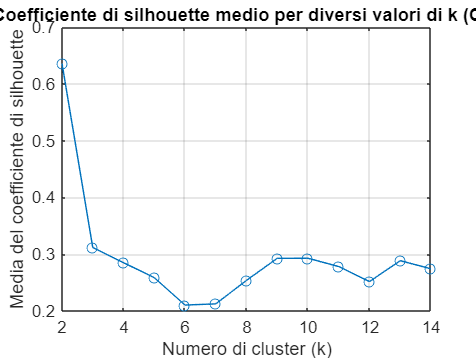

rng('default'); % Fissa il seed per la riproducibilità dei risultati

max_k = 14; % Numero massimo di cluster da provare
silhouette_values = zeros(1, max_k - 1);
num_trials = 5; % Numero di esecuzioni per ciascun valore di k

for k = 2:max_k
    best_silhouette = -Inf; % Inizializza al valore minimo possibile
    
    % Esegue il K-Means più volte e sceglie la miglior silhouette
    for trial = 1:num_trials
        % Usa K-Means++ per l'inizializzazione dei centroidi
        [idx, ~] = kmeans(matrice_misure, k, 'Distance', 'cityblock', 'Start', 'plus', 'Replicates', 10);
        
        % Calcola il coefficiente di silhouette
        s = silhouette(matrice_misure, idx);
        mean_silhouette = mean(s); % Calcola la media del coefficiente di silhouette
        
        if mean_silhouette > best_silhouette
            best_silhouette = mean_silhouette; % Aggiorna il miglior silhouette
            best_idx = idx; % Salva il miglior raggruppamento trovato
        end
    end
    
    silhouette_values(k-1) = best_silhouette; % Memorizza il miglior valore trovato per k
end

% Grafico per l'analisi del coefficiente di silhouette
figure;
plot(2:max_k, silhouette_values, '-o');
xlabel('Numero di cluster (k)');
ylabel('Media del coefficiente di silhouette');
title('Coefficiente di silhouette medio per diversi valori di k (CB)');
grid on;

clf; % Pulisce la finestra grafica

% Seleziona il miglior valore di k
[~, optimal_k] = max(silhouette_values); % Escludo il valore massimo, sono interessata
                                         % solo a che k corrisonde
optimal_k = optimal_k + 1; % Aggiungi 1 per il corretto indice
disp(['Numero ottimale di cluster: ', num2str(optimal_k)]);

Numero ottimale di cluster: 2


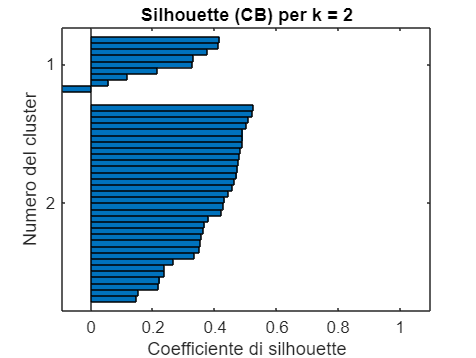


% Applica il k-means con distanza Manhattan/cityblock al valore ottimale
[idxcb, C] = kmeans(matrice_misure, optimal_k, 'Distance', 'cityblock', 'Start', 'plus', 'Replicates', 10);

% Visualizzazione della silhouette per il numero ottimale di cluster
figure;
silhouette(matrice_misure, idxcb, 'cityblock');
ylabel('Numero del cluster');
xlabel('Coefficiente di silhouette');
title(['Silhouette (CB) per k = ', num2str(optimal_k)]);

clf; % Pulisce la finestra grafica

% Trova i raggruppamenti unici
raggruppamenti_cb = unique(idxcb);

% Per ogni raggruppamento, stampa i sensori che ne fanno parte
for i = 1:length(raggruppamenti_cb)
    % Trova i sensori che appartengono a questo raggruppamento
    sensori = find(idxcb == raggruppamenti_cb(i));
    
    % Crea la stringa per i sensori separati da virgola
    sensori_str = strjoin(arrayfun(@num2str, sensori, 'UniformOutput', false), ', ');
    
    % Stampa il raggruppamento e i sensori corrispondenti
    fprintf('Raggruppamento %d: sensori %s\n', raggruppamenti_cb(i), sensori_str);
end

Raggruppamento 1: sensori 18, 19, 20, 21, 22, 23, 24, 25, 26
Raggruppamento 2: sensori 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 27, 28, 29, 30, 31, 32, 33, 34, 35, 36, 37, 38, 39, 40, 41


# Distanza euclidea quadratica (squared euclidean distance metric)

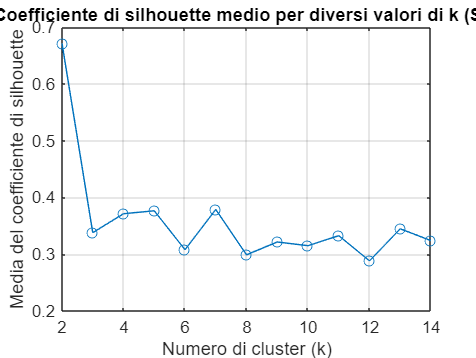

rng('default'); % Fissa il seed per la riproducibilità dei risultati

max_k = 14; % Numero massimo di cluster da provare
silhouette_values = zeros(1, max_k - 1);
num_trials = 5; % Numero di esecuzioni per ciascun valore di k

for k = 2:max_k
    best_silhouette = -Inf; % Inizializza al valore minimo possibile
    
    % Esegue il K-Means più volte e sceglie la miglior silhouette
    for trial = 1:num_trials
        % Usa K-Means++ per l'inizializzazione dei centroidi
        [idx, ~] = kmeans(matrice_misure, k, 'Distance', 'sqeuclidean', 'Start', 'plus', 'Replicates', 10);
        
        % Calcola il coefficiente di silhouette
        s = silhouette(matrice_misure, idx);
        mean_silhouette = mean(s); % Calcola la media del coefficiente di silhouette
         if mean_silhouette > best_silhouette
            best_silhouette = mean_silhouette; % Aggiorna il miglior silhouette
            best_idx = idx; % Salva il miglior raggruppamento trovato
        end
    end
    
    silhouette_values(k-1) = best_silhouette; % Memorizza il miglior valore trovato per k
end

% Grafico per l'analisi del coefficiente di silhouette
figure;
plot(2:max_k, silhouette_values, '-o');
xlabel('Numero di cluster (k)');
ylabel('Media del coefficiente di silhouette');
title('Coefficiente di silhouette medio per diversi valori di k (SE)');
grid on;

clf; % Pulisce la finestra grafica

% Seleziona il miglior valore di k
[~, optimal_k] = max(silhouette_values); % Escludo il valore massimo, sono interessata
                                         % solo a che k corrisonde
optimal_k = optimal_k + 1; % Aggiungi 1 per il corretto indice
disp(['Numero ottimale di cluster: ', num2str(optimal_k)]);

Numero ottimale di cluster: 2


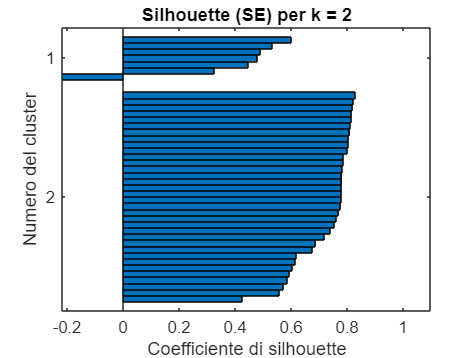


% Applica il k-means con distanza Euclidea al valore ottimale
[idxse, C] = kmeans(matrice_misure, optimal_k, 'Distance', 'sqeuclidean', 'Start', 'plus', 'Replicates', 10);

% Visualizzazione della silhouette per il numero ottimale di cluster
figure;
silhouette(matrice_misure, idxse, 'sqeuclidean');
ylabel('Numero del cluster');
xlabel('Coefficiente di silhouette');
title(['Silhouette (SE) per k = ', num2str(optimal_k)]);

clf; % Pulisce la finestra grafica

% Trova i raggruppamenti unici
raggruppamenti_sq = unique(idxse);

% Per ogni raggruppamento, stampa i sensori che ne fanno parte
for i = 1:length(raggruppamenti_sq)
    % Trova i sensori che appartengono a questo raggruppamento
    sensori = find(idxse == raggruppamenti_sq(i));
    
    % Crea la stringa per i sensori separati da virgola
    sensori_str = strjoin(arrayfun(@num2str, sensori, 'UniformOutput', false), ', ');
    
    % Stampa il raggruppamento e i sensori corrispondenti
    fprintf('Raggruppamento %d: sensori %s\n', raggruppamenti_sq(i), sensori_str);
end

Raggruppamento 1: sensori 18, 19, 20, 21, 22, 25, 26
Raggruppamento 2: sensori 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 23, 24, 27, 28, 29, 30, 31, 32, 33, 34, 35, 36, 37, 38, 39, 40, 41


## Si ipotizza che il sensore x sia guasto per un certo intervallo di tempo e si ricostruisce il suo segnale misura a partire dal segnale media dei sensori appartenenti ai vari tipi di clustering (di cui il sensore in questione fa parte)

% Ipotesi sensore guasto n.:
sensore_x = 2;

% Ipotesi intervallo temporale di misura del guasto:
colonne_corrispondenti = 1:6000;

# Distanza cityblock/Manhattan (cityblock/Manhattan distance metric)

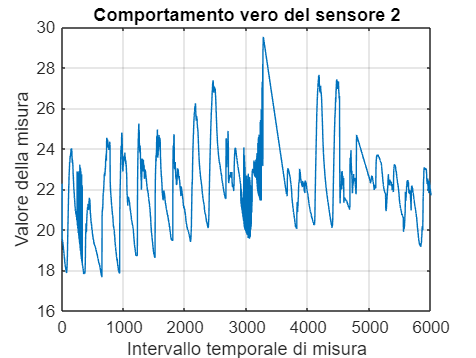

% Estrae il valore dell'elemento alla riga x di idx_cb
valore_raggrsens = idxcb(sensore_x);

% Trova tutte le righe che hanno lo stesso valore
righe_corrispondenti = find(idxcb == valore_raggrsens);

% Estrazione delle righe e colonne corrispondenti
matrice_estratta = matrice_misure(righe_corrispondenti, colonne_corrispondenti);

% Estrae la riga del sensore_x e le colonne dell'intervallo temporale di misura
dati_riga = matrice_misure(sensore_x, colonne_corrispondenti);

% Plot comportamento vero del sensore_x
figure; % Crea una nuova figura
comp_vero = plot(colonne_corrispondenti, dati_riga);
xlabel('Intervallo temporale di misura');
ylabel('Valore della misura');
title(['Comportamento vero del sensore ' num2str(sensore_x)]);
grid on; % Aggiunge la griglia al grafico

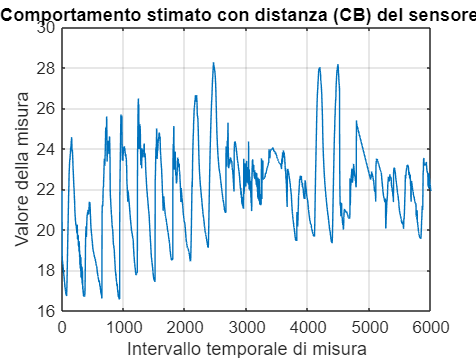


% Creiamo una matrice che esclude la riga associata al sensore_x
% Trova l'indice della riga uguale a dati_riga
indice_riga = find(all(matrice_estratta == dati_riga, 2));

% Rimuovi la riga corrispondente
matrice_estratta(indice_riga, :) = [];

% Calcoliamo la media delle colonne della matrice senza la riga sensore_x
media_colonne = mean(matrice_estratta, 1);

% Creiamo il nuovo vettore dati_rigacb
dati_rigacb = media_colonne;

comp_cb = plot(colonne_corrispondenti, dati_rigacb);
xlabel('Intervallo temporale di misura');
ylabel('Valore della misura');
title(['Comportamento stimato con distanza (CB) del sensore ' num2str(sensore_x)]);
grid on; % Aggiunge la griglia al grafico


clf; % Pulisce la finestra grafica

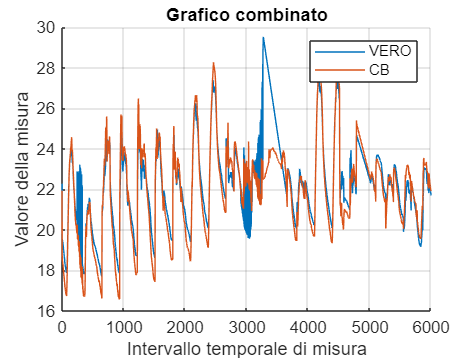

figure; % Crea una nuova figura
hold on;
comp_vero = plot(colonne_corrispondenti, dati_riga);
comp_cb = plot(colonne_corrispondenti, dati_rigacb);
xlabel('Intervallo temporale di misura');
ylabel('Valore della misura');
legend('VERO', 'CB');
title('Grafico combinato');
grid on; % Aggiunge la griglia al grafico
hold off;


clf; % Pulisce la finestra grafica

# Distanza euclidea quadratica (squared euclidean distance metric)

% Estrae il valore dell'elemento alla riga x di idx_se
valore_raggrsens = idxse(sensore_x);

% Trova tutte le righe che hanno lo stesso valore
righe_corrispondenti = find(idxse == valore_raggrsens);

% Estrazione delle righe e colonne corrispondenti
matrice_estratta = matrice_misure(righe_corrispondenti, colonne_corrispondenti);

% Estrae la riga del sensore_x e le colonne dell'intervallo di misura
dati_riga = matrice_misure(sensore_x, colonne_corrispondenti);

% Plot comportamento vero del sensore x
figure; % Crea una nuova figura
comp_vero = plot(colonne_corrispondenti, dati_riga);
xlabel('Intervallo temporale di misura');
ylabel('Valore della misura');
title(['Comportamento vero del sensore ' num2str(sensore_x)]);
grid on; % Aggiunge la griglia al grafico

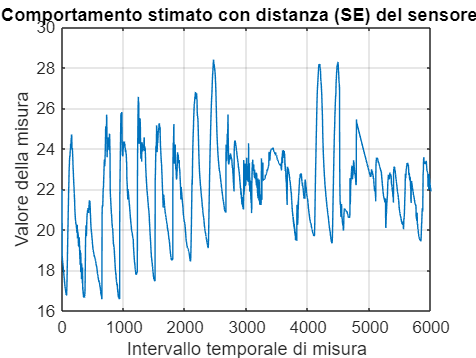


% Creiamo una matrice che esclude la riga associata al sensore_x
% Trova l'indice della riga uguale a dati_riga
indice_riga = find(all(matrice_estratta == dati_riga, 2));

% Rimuovi la riga corrispondente
matrice_estratta(indice_riga, :) = [];

% Calcoliamo la media delle colonne della matrice senza la riga sensore_x
media_colonne = mean(matrice_estratta, 1);

% Creiamo il nuovo vettore dati_rigacb
dati_rigase = media_colonne;

comp_se = plot(colonne_corrispondenti, dati_rigase);
xlabel('Intervallo temporale di misura');
ylabel('Valore della misura');
title(['Comportamento stimato con distanza (SE) del sensore ' num2str(sensore_x)]);
grid on; % Aggiunge la griglia al grafico


clf; % Pulisce la finestra grafica

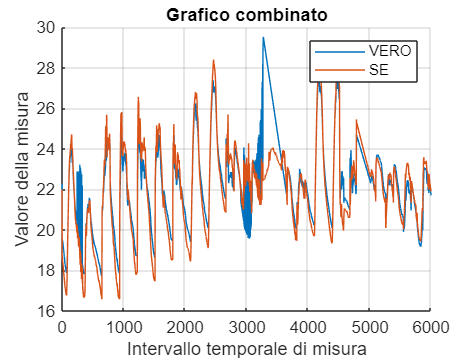

figure; % Crea una nuova figura
hold on;
comp_vero = plot(colonne_corrispondenti, dati_riga);
comp_se = plot(colonne_corrispondenti, dati_rigase);
xlabel('Intervallo temporale di misura');
ylabel('Valore della misura');
legend('VERO', 'SE');
title('Grafico combinato');
grid on; % Aggiunge la griglia al grafico
hold off;


clf; % Pulisce la finestra grafica

# Residui messi a confronto // Cross-Error function

## Definita come la differenza tra l’uscita/misura osservata (ỹ_x) e quella stimata (ŷ_x) nello stesso istante temporale.

% misura osservata è contenuta nel vettore dati_riga
% misura stimata è contenuta in dati_rigacb e dati rigase

cef_cb = dati_riga - dati_rigacb;

cef_se = dati_riga - dati_rigase;

% Calcolare l'errore quadratico medio
errore_quadratico_mediocb = sqrt(mean((cef_cb).^2));

% Visualizzare il risultato
disp(['L''errore quadratico medio (RMSE) per (CB) è: ', num2str(errore_quadratico_mediocb)]);

L'errore quadratico medio (RMSE) per (CB) è: 1.1363



% Calcolare l'errore quadratico medio
errore_quadratico_mediose = sqrt(mean((cef_se).^2));

% Visualizzare il risultato
disp(['L''errore quadratico medio (RMSE) per (SE) è: ', num2str(errore_quadratico_mediose)]);

L'errore quadratico medio (RMSE) per (SE) è: 1.1577


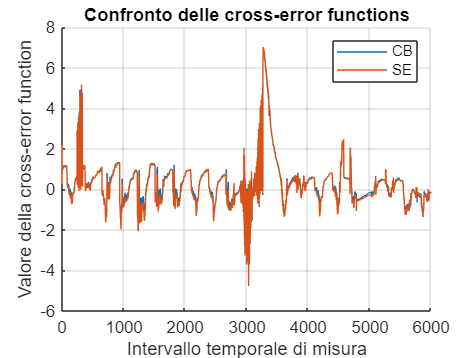


figure; % Crea una nuova figura
hold on;
plot(colonne_corrispondenti, cef_cb);
plot(colonne_corrispondenti, cef_se);

xlabel('Intervallo temporale di misura');
ylabel('Valore della cross-error function');
legend('CB', 'SE');
title('Confronto delle cross-error functions');
grid on; % Aggiunge la griglia al grafico
hold off;


clf; % Pulisce la finestra grafica